## **Problem 1**

Both parts require a set of *h *values and the function $f\left(x\right)$.

format long e

L = 12; %change L to make graph below run for smaller numbers like L=18
h = zeros(1, L);
for i = 1:L
    h(i) = 10.^(-i);
end
f = @(x) sin(x) - cos(x);
df = @(x) cos(x) + sin(x);

### ***a)***

%two point fwd
tp = @(x0, h) (f(x0 + h) - f(x0)) ./ h;
abs_errors_tp = arrayfun(@(h) abs(tp(0, h) - df(0)), h);

abs_errors_tp =      4.829251368802501e-02     4.983291750138896e-03     4.998332916459347e-04     4.999833314123237e-05     4.999984760445386e-06     5.000732059556867e-07     4.943368026033568e-08     5.024759275329416e-09     2.828193157444758e-08     8.274037099909037e-08     8.274037099909037e-08     2.212172012150404e-05


***b)***

%Three-Point Midpoint
tpm = @(x0, h) (1./ (2*h)) * ( f(x0 + h) - f(x0 - h) );
abs_errors_tpm = arrayfun(@(h) abs(tpm(0, h) - df(0)), h);

abs_errors_tpm =      1.665833531717897e-03     1.666658333476789e-05     1.666666240573988e-07     1.667110005598715e-09     1.565314544649254e-11     2.675548671504657e-11     5.263558477963670e-10     5.263558477963670e-10     2.722921954578794e-08     8.274037099909037e-08     8.274037077704577e-08     3.338943110975379e-05


***Logarithmic plot***

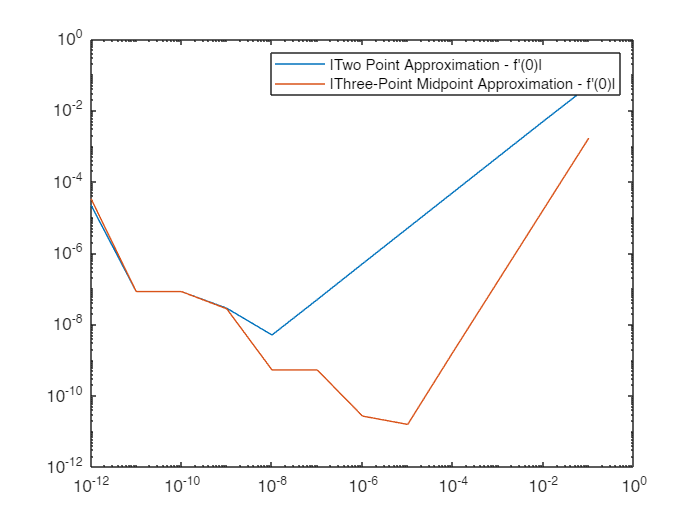

loglog(h,abs_errors_tp, h, abs_errors_tpm);
legend("|Two Point Approximation - f'(0)|", "|Three-Point Midpoint Approximation - f'(0)|");

**Error Term Domination**

For the two point formula the error term starts to take over at $h\approx {10}^{-8}$ while for the three point it occurs at $h\approx {10}^{-5}$ .